# Extras: Designing Lead and Lag Compensators

Lead and lag compensators are used quite extensively in control. A lead compensator (also referred to as a phase-lead compensator) can increase the stability or speed of response of a system; a lag compensator (also referred to as a phase-lag compensator) can reduce (but not eliminate) the steady-state error. Depending on the effect desired, one or more lead and lag compensators may be used in various combinations.

Lead, lag, and lead/lag compensators are usually designed for a system in transfer function form. The [conversions](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Conversions) page explains how to convert a state-space model into transfer function form.

## Lead (phase-lead) compensator using root locus

A first-order lead compensator $C\left(s\right)$ can be designed using the root locus. A lead compensator in root locus form is given by


$$ C(s)=K_{c}\frac{(s-z_{0})}{(s-p_{0})} $$


where the magnitude of $z_0$ is less than the magnitude of $p_0$. A phase-lead compensator tends to shift the root locus toward to the left in the complex *s*-plane. This results in an improvement in the system's stability and an increase in its response speed.

How is this accomplished? If you recall finding the asymptotes of the root locus that lead to the zeros at infinity, the equation to determine the intersection of the asymptotes along the real axis is the following.


$$ \sigma_a=\frac{\sum(poles)-\sum(zeros)}{(\#poles)-(\#zeros)} $$


When a lead compensator is added to a system, the value of this intersection will be a larger negative number than it was before. The net number of zeros and poles will be same (one zero and one pole are added), but the added pole is a larger negative number than the added zero. Thus, the result of a lead compensator is that the asymptotes' intersection is moved further to the left in the complex plane, and the entire root locus is shifted to the left as well. This tends to increase the region of stability and the system's response speed. The following live script demonstrates the effect of the addition of a lead compensator on a feedback system's root locus plot for a specific plant and compensator by choosing a selection from the drop-down menu. The resulting asymptote is drawn as a yellow line.

s = tf('s');
P = 1/(s*(s+1));
a(1) = (sum(pole(P)) - sum(zero(P))) / (length(pole(P)) - length(zero(P)));
Clead = 1.2*(s+2)/(s+4.2); 
a(2) = (sum(pole(P*Clead)) - sum(zero(P*Clead))) / (length(pole(P*Clead)) - length(zero(P*Clead)));
plot([a(1) a(1)],[-15 15],'Color',[1 0.93 0.47],'LineWidth',5);text(-3.5,2, "Asymptotes' interaction is at " + num2str(a(1)));hold on;rlocus(P);
axis([-5 1 -15 15])
hold off

## Lead (phase-lead) compensator using frequency response

A first-order phase-lead compensator can also be designed using a frequency response approach. A lead compensator in frequency response form is given by the following.


$$ C(s) = \frac{1+aTs}{1+Ts} \qquad [ a>1 ] $$


Note that this is equivalent to the root locus form repeated below


$$ C(s)=K_{c}\frac{(s-z_{0})}{(s-p_{0})} $$


with $p_0 =\frac{-1}{T}$, $z_0 =\frac{-1}{\textrm{aT}}$, and $K_c =a$. In frequency response design, the phase-lead compensator adds positive phase to the system over the approximate frequency range $\frac{1}{\textrm{aT}}$ to $\frac{1}{T}$, the location of the two corner frequencies. An example lead compensator's Bode plot is shown below: 

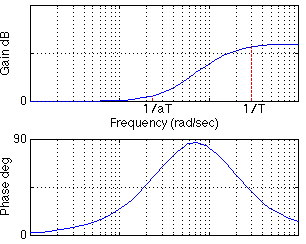

The value of $a$ (the ratio between the magnitude of the pole and the magnitude of the zero) affects the amount of positive phase added to the system. Spreading the pole and zero farther apart adds more positive phase, where the maximum amount of phase that can be added is 90 degrees. If you need more than 90 degrees of phase, two lead compensators in series can be employed. The additional positive phase can be used to increase the phase margin and thus increases the stability of the system. 

Consider the Bode plot of a phase-lead compensator $C\left(s\right)$ shown below. With the slider you can vary the value of the parameter $a$ and observe the effect of altering the ratio between the compensator pole and zero.

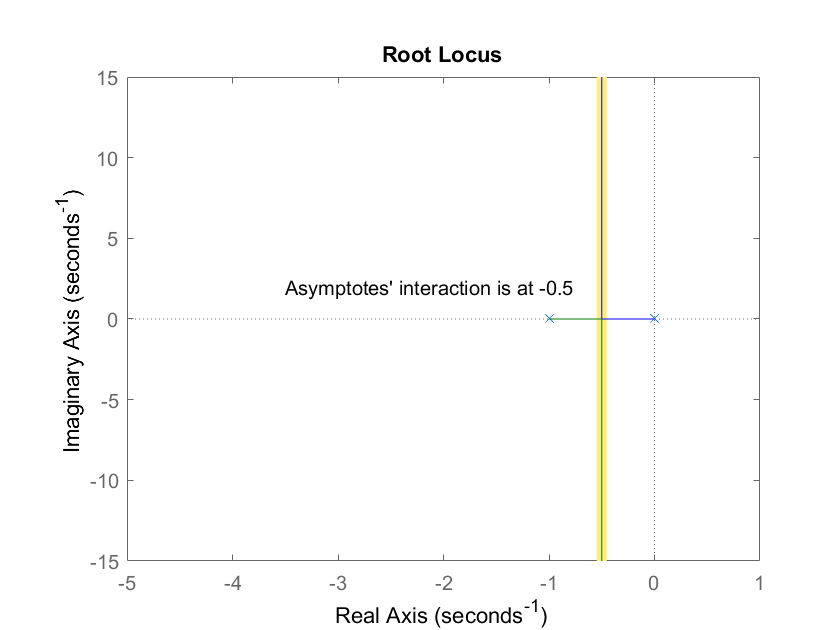

a =10;
T = 1; 
s = tf('s');
C = (1+a*T*s)/(1+T*s);
bode(C); title('Bode Diagram of a Lead Compensator')
grid on
axis([0.0001 100 0 90])
displayPoleZero(a,T) 

As expected, increasing the ratio between the pole and zero leads to more phase lead being added by the compensator. You can also notice that increasing the parameter $a$ causes additional magnitude to be added to the system at higher frequencies.

In the previous example, the value of the parameter $T$ was kept constant. If the ratio $a$ is kept constant, varying the value of $T$ shifts the pole and zero such that the frequency where the phase lead is added is altered, while otherwise maintaining the shape of the Bode plot. In the following, the effect of altering $T$ on the resulting Bode plot can be observed.

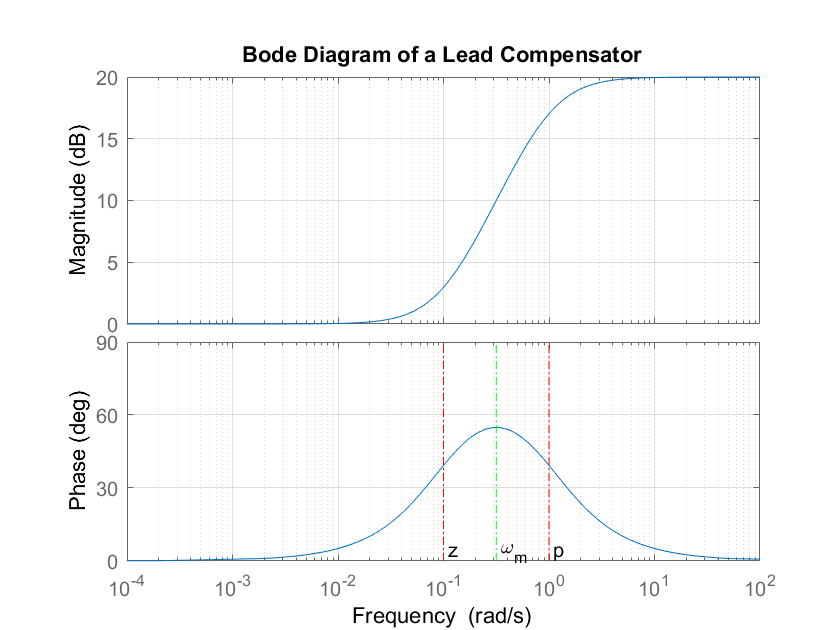

a = 50;
T = 1; 
s = tf('s');
C = (1+a*T*s)/(1+T*s);
bode(C); title('Bode Diagram of a Lead Compensator')
grid on
axis([0.0001 10 0 90])
displayPoleZero(a,T) 

In conclusion, we can design our lead compensator through our choice of the parameters $a$ and $T$. Specifically, the ratio $a$ determines the maximum amount of additional phase $\phi$ according to the following equation:


$$\sin\phi=\frac{a-1}{a+1}$$


Then the parameter $T$ can be selected to affect the location where the phase is added, typically at the new gain crossover frequency. Specifically, the maximum amount of phase is added at the center frequency $\omega_m$ which is the geometric mean of the pole and zero. This frequency is calculated as follows:


$$\omega_{m}=\frac{1}{T\sqrt{a}}$$


Recall, another effect of the lead compensator is to increase the gain of the system at high frequencies (the amount of this gain is equal to $a$). This can increase the gain crossover frequency, which will help to decrease the rise time and settling time of the system (but may amplify high frequency noise).

## Lag (phase-lag) compensator using root locus

A first-order lag compensator $C\left(s\right)$can be designed using the root locus. A lag compensator in root locus form is given by the following.


$$ C(s) = \frac{(s-z_{0})}{(s-p_{0})} $$


This has a similar form to a lead compensator, except now the magnitude of $z_0$ is greater than the magnitude of $p_0$ (and the additional gain $K_c$ is omitted). A phase-lag compensator tends to shift the root locus to the right in the complex *s*-plane, which is undesirable. For this reason, the pole and zero of a lag compensator are often placed close together (usually near the origin) so that they do not appreciably change the transient response or stability characteristics of the system.

How does the lag controller shift the root locus to the right? Below is repeated the equation for finding where the asymptotes of the root locus intersect along the real axis.


$$ \sigma_a=\frac{\sum(poles)-\sum(zeros)}{(\#poles)-(\#zeros)}$$


When a lag compensator is added to a system, the value of this intersection will be a smaller negative number than it was before. The net number of zeros and poles will be the same (one zero and one pole are added), but the added pole is a smaller negative number than the added zero. Thus, the result of a lag compensator is that the asymptotes' intersection is moved to the right in the complex plane, and the entire root locus is shifted to the right as well.

It was previously stated that a lag compensator is often designed to minimally change the transient response of system because it generally has a negative effect. If the phase-lag compensator is not supposed to change the transient response noticeably, what is it good for then? The answer is that a phase-lag compensator can improve the system's steady-state response. It works in the following manner. At high frequencies, the lag compensator will have unity gain. At low frequencies, the gain will be $\frac{z_0 }{p_0 }$ which is greater than 1. This $\frac{z_0 }{p_0 }$ factor will multiply the position, velocity, or acceleration constant ($K_p$, $K_v$, or $K_a$), and the [steady-state error](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Ess) will thus decrease by the same factor. 

## Lag (phase-lag) compensator using frequency response

A first-order phase-lag compensator also can be designed using a frequency response approach. A lag compensator in frequency response form is given by the following.


$$C(s)=\frac{1}{a}\left(\frac{1+aTs}{1+Ts}\right) \qquad [ a<1 ]$$


The phase-lag compensator looks similar to a phase-lead compensator, except that $a$ is now less than 1. The main difference is that the lag compensator adds negative phase to the system over the specified frequency range, while a lead compensator adds positive phase over the specified frequency, between the two corner frequencies $\frac{1}{T}$ and $\frac{1}{\textrm{aT}}$. The form of the Bode plot is shown below:

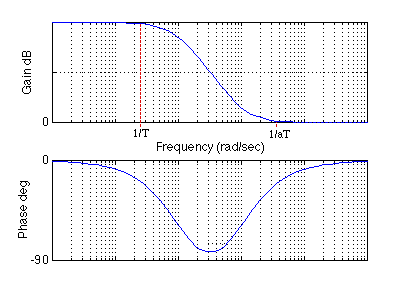

The main effect of the lag compensator is seen in the magnitude plot. The lag compensator adds gain at low frequencies; the magnitude of this gain is equal to $\frac{1}{a}$. The primary goal of adding this additional DC gain is to cause the [steady-state error](https://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Ess) of the closed-loop system to decrease. Because the gain of the lag compensator is unity at middle and high frequencies, the transient response and stability are generally not impacted much.

The side effect of the lag compensator is the negative phase that is added to the system between the two corner frequencies. Depending on the value $a$, up to -90 degrees of phase can be added. Care must be taken that the phase margin of the system with lag compensation is still satisfactory. This is generally achieved by placing the frequency of maximum phase lag, $\omega_m$ as calculated below, well below the new gain crossover frequency.


$$\omega_{m}=\frac{1}{T\sqrt{a}}$$


The following interactive script allows you to see the effect of the parameters $a$ and $T$ on the resulting Bode plot of a lag compensator.

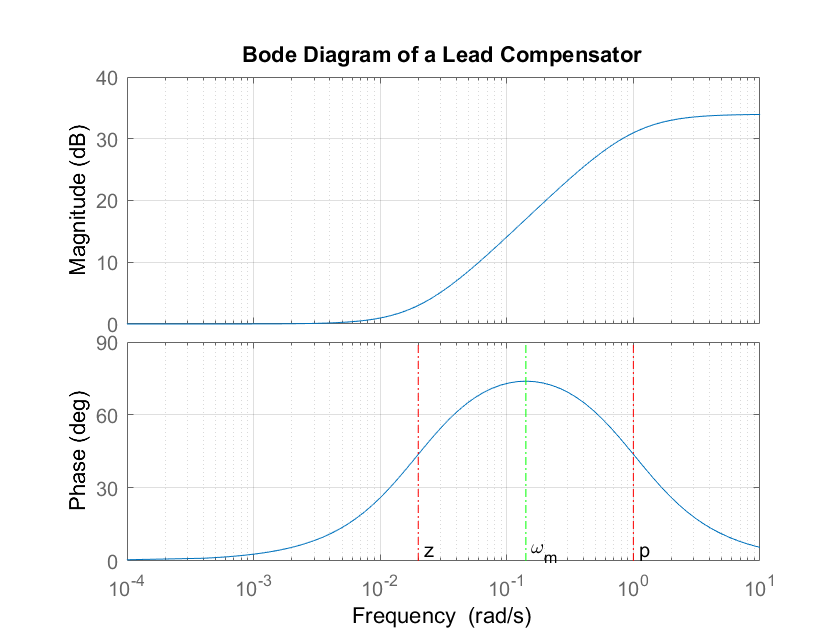

a =0.2;
T = 1; 
s = tf('s');
C = (1/a)*(1+a*T*s)/(1+T*s);
bode(C); title('Bode Diagram of a Lag Compensator')
grid on
axis([0.001 1000 -90 0])
displayZeroPole(a,T) 

As expected, increasing the separation between the pole and zero (parameter $a$) increased the DC gain of the system and altering the parameter $T$ shifted where the maximum phase lag is added. 

## Lead-lag compensator using either root locus or frequency response

A lead-lag compensator combines the effects of a lead compensator with those of a lag compensator. The result is a system with improved transient response, stability, and steady-state error. To implement a lead-lag compensator, first design the lead compensator to achieve the desired transient response and stability, and then design a lag compensator to improve the steady-state response of the lead-compensated system. 

*The following functions are used in the script above.*

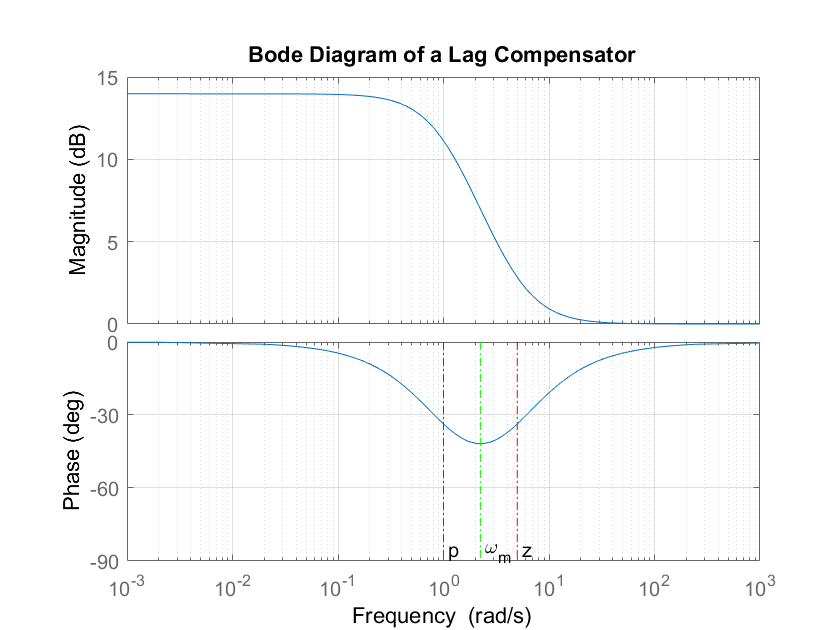

function displayPoleZero(a, T) 
z = 1/(a*T);
p = 1/T;
wm = 1/(T*sqrt(a));
hold on;
plot([z z],[0 90],'r-.');
text(z*1.1,5,'z');
plot([p p],[0 90],'r-.');

text(p*1.1,5,'p');
plot([wm wm],[0 90],'g-.');
text(wm*1.1,5,'\omega_m');
hold off;
end

function displayZeroPole(a, T) 
z = 1/(a*T);
p = 1/T;
wm = 1/(T*sqrt(a));
hold on;
plot([z z],[0 -90],'r-.');
text(z*1.1,-85,'z');
plot([p p],[0 -90],'r-.');
text(p*1.1,-85,'p');
plot([wm wm],[0 -90],'g-.');
text(wm*1.1,-85,'\omega_m');
hold off;
end